# Bespoke Noise Generator

This script applies a scaled noise correction to meet a user defined SNR. It:

- calculates the signal power for each element of the baseline data (complex array input).

- determines the required noise power to achieve the desired SNR.

- generates the complex noise matrix for each element.

- adds the noise matrix to the original matrix to create the noisy matrix.

- the noisy matrix is then processed by the slice_SNR function.

- the baseline SNR vs noisy matrix SNR is visualised; as well as the SNR, Signal and Noise for each the Baseline and the Noisy data across subplots.

active_required_SNR_dB = 15; % Desired SNR in dB [dB].
active_required_SNR_linear = 10^(active_required_SNR_dB / 10); % [linear]

active_baseline_matrix_complex = active_inputdata; % [complex]
active_baseline_matrix_linear = active_slices_range_doppler_abs; % [linear]

% Calculate signal power for each element
active_signalPower_linear = zeros(1, length(active_baseline_matrix_linear)); % [linear]
for i = 1:length(active_baseline_matrix_linear)
    active_signalPower_linear(i) = (max(active_baseline_matrix_linear{i}(:))).^2; % [linear]
end

% Calculate noise power for each element
active_noisePower_linear = active_signalPower_linear / active_required_SNR_linear; % [linear]

% Generate a noise matrix for each element
active_noise_complex = cell(1, length(active_baseline_matrix_complex));
for i = 1:length(active_baseline_matrix_complex)
    % Use sqrt(noisePower_linear(i)/2) for complex noise
    active_noise_complex{i} = sqrt(active_noisePower_linear(i)/2) * ...
        (randn(size(active_baseline_matrix_complex{i})) + 1i .* randn(size(active_baseline_matrix_complex{i}))); % [complex]
end

% Add the original matrix to the new noise matrix
active_noisyMatrix_complex = cell(1, length(active_baseline_matrix_complex));
for i = 1:length(active_baseline_matrix_complex)
    active_noisyMatrix_complex{i} = active_baseline_matrix_complex{i} + active_noise_complex{i};
end

% Calculate linear and dB values for each element in noise_complex
active_noise_linear = cell(1, length(active_noise_complex));
active_noise_dB = cell(1, length(active_noise_complex));
for i = 1:length(active_noise_complex)
    active_noise_linear{i} = abs(active_noise_complex{i});  % Linear values
    active_noise_dB{i} = 20*log10(abs(active_noise_complex{i}));  % dB values
end

% Add the original matrix to the new noise matrix to generate the noisy matrix
active_noisyMatrix_complex = cell(1, length(active_baseline_matrix_complex));
for i = 1:length(active_baseline_matrix_complex)
    active_noisyMatrix_complex{i} = active_baseline_matrix_complex{i} + active_noise_complex{i}; % [complex]
end  

### Use slice_SNR to process the noisyMatrix

% User defined ROI indices
active_roi_indices_rows = 320:420; % input to slice_SNR func to calculate noise of roi
active_roi_indices_cols = 65:99;   % input to slice_SNR func to calculate noise of roi
noisy_active_signal=zeros(1,length(active_noisyMatrix_complex)); % [dB] once func populates
noisy_active_noise=zeros(1,length(active_noisyMatrix_complex)); % [dB] once func populates
noisy_active_noise_abs=zeros(1,length(active_noisyMatrix_complex)); % absolute mean noise (not dB) once func populates
noisy_active_SNR=zeros(1,length(active_noisyMatrix_complex)); % [dB] once func populates
noisy_active_slices_range_doppler = createArrays(length(active_noisyMatrix_complex), size(active_noisyMatrix_complex{1,1})); % [dB] once func populates
noisy_active_slices_range_doppler_abs = createArrays(length(active_noisyMatrix_complex), size(active_noisyMatrix_complex{1,1})); % absolute not dB, once func populates
noisy_active_signal_idx = zeros(1,length(active_noisyMatrix_complex));

for i=1:length(active_noisyMatrix_complex)
    [noisy_active_signal(i),...
        noisy_active_noise(i),...
        noisy_active_SNR(i),...
        noisy_active_slices_range_doppler{i},...
        noisy_active_signal_idx(i),...
        noisy_active_noise_abs(i),...
        noisy_active_slices_range_doppler_abs{i}]=slice_SNR(active_noisyMatrix_complex{1,i}, active_roi_indices_rows, active_roi_indices_cols);
end   

Calculating Mean Values for Plot

active_mean_active_SNR_dB = mean(active_SNR) % mean mean of the baseline SNR [db]

active_mean_active_SNR_dB = 59.4181

active_mean_noisy_active_SNR_dB = mean(noisy_active_SNR) % mean of the noise SNR [dB]

active_mean_noisy_active_SNR_dB = 16.3514

active_mean_delta = -(active_mean_active_SNR_dB - active_mean_noisy_active_SNR_dB) % - to show reduction [dB]

active_mean_delta = -43.0668

### Visualising the Baseline Matrix & the Noisy Matrix

figure;
fig = figure;
subplot(3,1,1)
plot(1:length(active_SNR), active_SNR, ...
    1:length(noisy_active_SNR), noisy_active_SNR)

grid minor
title('SNR, Signal & Noise Comparison - Baseline vs Noisy');
ylabel('Noise [dB]');
xlabel('Slice Number');
xlim([1, length(active_SNR)])
% Add text annotations
text(1, (active_SNR(1:1))*1.05, 'Baseline SNR', ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'left');
text(1, (noisy_active_SNR(1:1))*1.05, 'Noisy SNR', ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'left');
yline(active_mean_active_SNR_dB, '--', ...
    ['Baseline SNR Mean: ' num2str(active_mean_active_SNR_dB)], ...
    'LineWidth', 0.25);
%    'FontSize', 6);
yline(active_mean_noisy_active_SNR_dB, '--', ...
    ['Noisy SNR Mean: ' num2str(active_mean_noisy_active_SNR_dB)], ...
    'LineWidth', 0.25);
%    'FontSize', 6);
legend( 'Baseline SNR [dB]', ...
    'Baseline Signal [dB]',  ...
    'location', 'best')

subplot(3,1,2)
plot(1:length(active_SNR), active_SNR, ...
    1:length(active_signal), active_signal, ...
    1:length(active_noise), active_noise)
legend( 'Baseline SNR [dB]', ...
    'Baseline Signal [dB]', ...
    'Baseline Noise [dB]',...
    'location', 'best')
grid minor
title('SNR, Signal & Noise Comparison - Baseline Matrix');
ylabel('Noise [dB]');
xlabel('Slice Number');
xlim([1, length(active_SNR)])
% Add text annotations
text(length(active_SNR), max(active_SNR), 'SNR', ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'right');
text(length(active_signal), max(active_signal), 'Signal', ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'right');
text(length(active_noise), max(active_noise), 'Noise', ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'right');

subplot(3,1,3)
plot(1:length(noisy_active_SNR), noisy_active_SNR, ...
    1:length(noisy_active_signal), noisy_active_signal, ...
    1:length(noisy_active_noise), noisy_active_noise)
legend( 'Noisy SNR [dB]', ...
    'Noisy Signal [dB]', ...
    'Noisy Noise [dB]',...
    'location', 'best')
grid minor
title('SNR, Signal & Noise - Noisy Matrix');
ylabel('Noise [dB]');
xlabel('Slice Number');
xlim([1, length(active_SNR)])
% Add text annotations
text(145, max(noisy_active_SNR), 'SNR', ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'right');
text(145, max(noisy_active_signal), 'Signal', ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'right');
text(145, max(noisy_active_noise), 'Noise', ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'right');

Save figure to repo

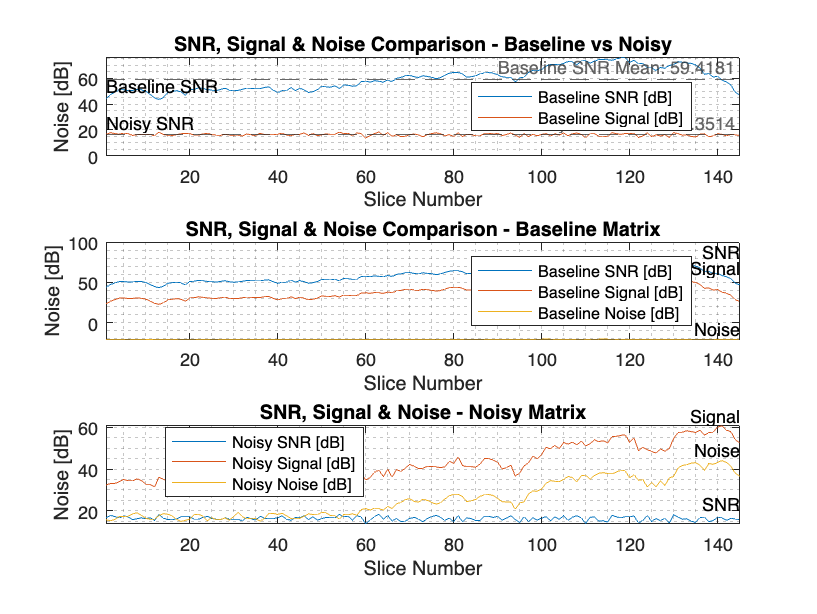

fig_name = figure_directory + bracket + 'Active SNR Signal & Noise - 3 subplots ';
saveas(fig, fig_name + '.png')

#### Observation:

The differences in the profiles of 'active_SNR' and the 'noisy_active_SNR' can be attributed to the nature of the signal and noise addition.

Baseline SNR ('active_SNR'):  this represents the Signal-to-Noise Ratio (SNR) of the original data. The profile shows the quality of the signal across different slices.

Noisy Signal SNR ('noisy_active_SNR'):  this represents the SNR after adding artificial noise to the original data. The artificial noise affects the SNR, and you are seeing a different profile due to the added noise. The flatter profile may indicate that the added noise is affecting different slices uniformly.

#### Plot Baseline SNR vs Noisy SNR vs Noisy SNR Zero Mean

Moving the Noisy SNR signal to have a mean = 0dB

noisy_active_SNR_dB_zeroed = noisy_active_SNR - active_mean_noisy_active_SNR_dB; % [dB]

Plot the Baseline SNR vs Noisy SNR vs Noisy SNR Zero Mean

figure_title = ('Active - Baseline SNR vs Noisy SNR vs Noisy SNR Zero Mean');
figure;
fig = figure;
plot(1:length(active_SNR), active_SNR, ...
    1:length(noisy_active_SNR), noisy_active_SNR, ...
    1:length(noisy_active_SNR_dB_zeroed), noisy_active_SNR_dB_zeroed)
yline(active_mean_active_SNR_dB, '--', ...
    ['Baseline SNR Mean: ' num2str(active_mean_active_SNR_dB)], ...
    'LineWidth', 0.25, ...
    'FontSize', 6);
yline(active_mean_noisy_active_SNR_dB, '--', ...
    ['Noisy SNR Mean: ' num2str(active_mean_noisy_active_SNR_dB)], ...
    'LineWidth', 0.25, ...
    'FontSize', 6);
legend( 'Baseline SNR [dB]', ...
    'Noisy Signal SNR [dB]', ...
    'Noisy Signal SNR Offset to Zero', '', '', ...
    'location', 'best')
grid minor
title(figure_title)
ylabel('Noise [dB]');
xlabel('Slice Number');
xlim([1, length(noisy_active_SNR)])

Save figure to repo

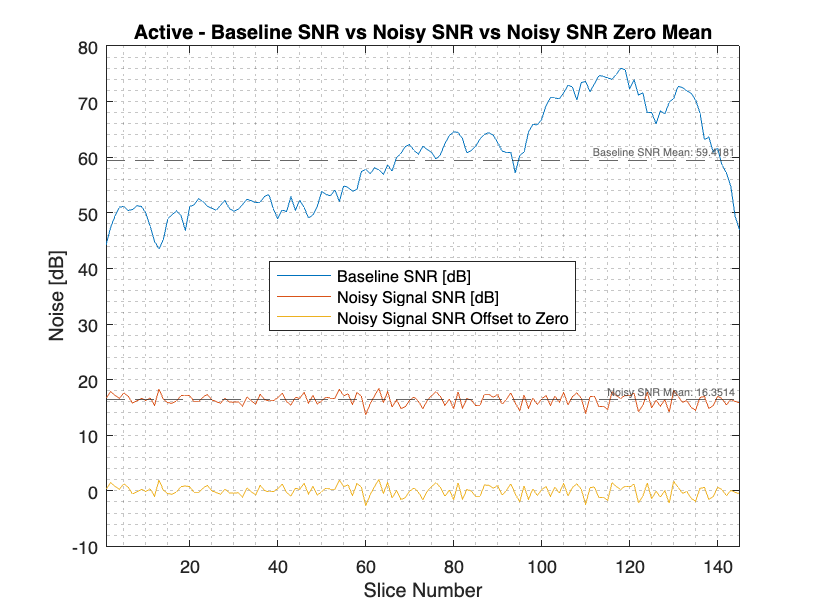

fig_name = figure_directory + bracket + figure_title;
saveas(fig, fig_name + '.png')